# [为自动驾驶定制虚幻引擎场景](https://ww2.mathworks.cn/help/releases/R2022b/driving/ug/customize-3d-scenes-for-automated-driving.html)

自动驾驶工具箱包含预建场景，可在其中模拟和可视化在 Simulink ®中建模的驾驶算法的性能。这些场景使用工具箱中独立的 Unreal Engine ®可执行文件进行可视化。如果您安装了Epic Games ®的Unreal ®编辑器和适用于[虚幻引擎](https://www.mathworks.com/matlabcentral/fileexchange/74555-automated-driving-toolbox-interface-for-unreal-engine-4-projects)[4 项目的](https://www.mathworks.com/matlabcentral/fileexchange/74555-automated-driving-toolbox-interface-for-unreal-engine-4-projects)[自动驾驶工具箱](https://www.mathworks.com/matlabcentral/fileexchange/74555-automated-driving-toolbox-interface-for-unreal-engine-4-projects)[界面](https://www.mathworks.com/matlabcentral/fileexchange/74555-automated-driving-toolbox-interface-for-unreal-engine-4-projects)，可以自定义这些场景。还可以使用虚幻编辑器和支持包在您自己的自定义项目的场景中进行模拟。

使用自定义场景，您可以在 Simulink 和 Unreal Editor 中进行联合仿真，以便您可以在仿真运行之间修改场景。您还可以将您的场景打包成一个可执行文件，这样您就不必打开编辑器来模拟这些场景。

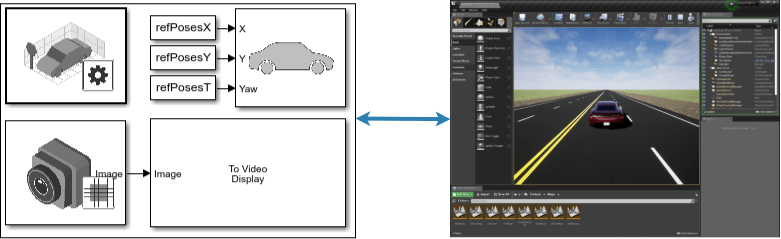

要为自动驾驶自定义虚幻引擎场景，请按照以下步骤操作：

- [安装自定义场景支持包](https://ww2.mathworks.cn/help/driving/ug/install-and-configure-support-package-for-customizing-scenes.html)

- [迁移使用先前支持包开发的项目](https://ww2.mathworks.cn/help/driving/ug/migrate-projects-developed-using-prior-support-packages.html)

- [使用 Simulink 和虚幻编辑器自定义场景](https://ww2.mathworks.cn/help/driving/ug/customize-scenes-using-simulink-and-unreal-editor.html)

- [将自定义场景打包成可执行文件](https://ww2.mathworks.cn/help/driving/ug/package-custom-scenes-into-executable.html)

## 安装自定义场景支持包

### **安装支持包**

要安装Automated Driving Toolbox™ Interface for Unreal Engine ® 4 Projects支持包。

**使用支持包设置场景自定义**

虚幻引擎 4 项目支持包的自动驾驶工具箱接口包括以下组件：

- `AutoVrtlEnv`文件夹——包含 `AutoVrtlEnv.uproject `文件和相应支持文件的虚幻引擎项目文件夹。该项目包含预构建场景的可编辑版本，您可以从[Simulation 3D 场景配置](https://ww2.mathworks.cn/help/driving/ref/simulation3dsceneconfiguration.html)块的 **场景名称** 参数中选择这些版本。

- `MathWorkSimulation`— 在 Simulink 和 Unreal Editor 之间建立连接的插件。它是联合仿真所必需的。

- `MathWorksAutomotiveContent`— 一个插件，包含可以使用虚幻编辑器修改的汽车对象元素。它是联合仿真所必需的。

- `RoadRunnerScenes`文件夹——包含虚幻引擎项目和场景的相应可执行文件的文件夹，该场景是使用RoadRunner场景编辑软件创建的。此文件夹包含以下子文件夹：

- `RRScene``RRScene.uproject`— 包含文件和相应支持文件的虚幻引擎项目文件夹 。该项目包含[在使用 RoadRunner 场景](https://ww2.mathworks.cn/help/driving/ug/highway-lane-following-with-roadrunner-scene.html)示例的公路车道跟踪中使用的场景的可编辑版本。

- `WindowsPackage`— 包含可执行文件 `RRScene.exe `和支持文件的文件夹。使用此可执行文件来共同仿真[Highway Lane Following with RoadRunner Scene](https://ww2.mathworks.cn/help/driving/ug/highway-lane-following-with-roadrunner-scene.html)示例中解释的 Simulink 模型。

- `RoadRunnerMaterials`— 包含 roadrunner 场景中物体特征的插件。

要设置场景自定义，您必须将 `AutoVrtlEnv`项目和`MathWorksSimulation` 插件文件夹复制到本地计算机上。要自定义[Highway Lane Following with RoadRunner Scene](https://ww2.mathworks.cn/help/driving/ug/highway-lane-following-with-roadrunner-scene.html)示例中使用的RoadRunner场景，您还必须将项目复制到本地计算机上，然后下载插件并将其复制到本地项目中。`RRScene``RoadRunnerMaterials`

安装并设置支持包后，您可以开始自定义场景。如果您想使用使用虚幻引擎 4 项目支持包的自动驾驶工具箱接口的先前版本开发的项目，您必须迁移该项目以使其与当前支持的虚幻编辑器版本兼容。请参阅[迁移使用先前支持包开发的项目](https://ww2.mathworks.cn/help/driving/ug/migrate-projects-developed-using-prior-support-packages.html)。否则，请参阅 [使用 Simulink 和虚幻编辑器自定义场景](https://ww2.mathworks.cn/help/driving/ug/customize-scenes-using-simulink-and-unreal-editor.html)。

**将**`AutoVrtlEnv`**项目复制到本地文件夹，** `MathWorksSimulation`**并将** `MathWorksAutomotiveContent`**插件复制到****虚幻****编辑器**

要将所有支持包组件复制到本地计算机上的文件夹并配置您的环境以便您可以自定义场景，请使用该[`copyExampleSim3dProject`](https://ww2.mathworks.cn/help/driving/ref/sim3d.utils.copyexamplesim3dproject.html)功能。例如，此代码将文件复制到 `C:\project。`

localFolder = 'C:\project';
sim3d.utils.copyExampleSim3dProject("C:\project", VerboseOutput=true);

**（可选）将 **`RRScene `**项目复制到本地文件夹**

要自定义项目文件夹中的场景，请将 `RRScene `项目复制到本地计算机上。

1.指定包含项目的支持包文件夹的路径。还要指定一个本地文件夹目标以复制项目。此代码使用前面部分中的支持包路径和本地文件夹路径。

rrProjectSupportPackageFolder = fullfile( ... 
    matlabshared.supportpkg.getSupportPackageRoot, ... 
    "toolbox" , "shared" , "sim3dprojects" , "driving" , ... 
    "RoadRunnerScenes" , "RRScene" );
rrProjectLocalFolder = fullfile(localFolder, "RRScene" );

2.将`RRScene`项目从支持包文件夹复制到本地目标文件夹。

if ~exist(rrProjectLocalFolder,"dir")
    copyfile(rrProjectSupportPackageFolder,rrProjectLocalFolder);
end

该`RRScene.uproject`文件及其所有支持文件现在位于`RRScene`指定本地文件夹内命名的文件夹中。例如：`C:\Local\RRScene`。

**（可选）将**`RoadRunnerMaterials`**插件复制到****虚幻****编辑器**

在`RRScene`项目文件夹中自定义场景时，还必须将`RoadRunnerMaterials`插件复制到您的插件项目文件夹中。

1.下载包含最新 RoadRunner 插件的 ZIP 文件。请参阅[下载插件](https://ww2.mathworks.cn/help/roadrunner/ug/downloading-plugins.html)(RoadRunner)。将 ZIP 文件的内容解压缩到本地计算机。提取的文件夹名称的形式为`RoadRunner Plugins x.x.x`，其中 `x.x.x`是插件版本号。

2.指定`RoadRunnerMaterials`插件的路径。该插件位于`Unreal/Plugins`解压文件夹的文件夹中。更新此代码以匹配您下载插件的位置和插件版本号。

rrMaterialsPluginFolder = fullfile( "C:" , "project" , "RoadRunner Plugins 1.3.1" , ... 
    "Unreal" , "Plugins" , "RoadRunnerMaterials" );

3.在您的本地`RRScene`项目中，创建一个 `Plugins`用于复制插件的文件夹。此代码使用`RRScene`上一节中指定的本地项目的路径。

rrProjectPluginFolder = fullfile(rrProjectLocalFolder, "Plugins" , "RoadRunnerMaterials" );

4.将`RoadRunnerMaterials`插件复制到 `Plugins`本地项目的文件夹中。

copyStatus = copyfile(rrMaterialsPluginFolder,rrProjectPluginFolder);
if copyStatus
    disp("Successfully copied RoadRunnerMaterials plugin to RRScene project plugins folder.")
else
    disp("Unable to copy RoadRunnerMaterials plugin to RRScene project plugins folder.")
end

安装并设置支持包后，您可以开始自定义场景。如果您想使用使用 虚幻引擎 4 项目支持包的自动驾驶工具箱接口的先前版本开发的项目，您必须迁移该项目以使其与当前支持的虚幻编辑器版本兼容。请参阅[迁移使用先前支持包开发的项目](https://ww2.mathworks.cn/help/driving/ug/migrate-projects-developed-using-prior-support-packages.html)。否则，请参阅[使用 Simulink 和虚幻编辑器自定义场景](https://ww2.mathworks.cn/help/driving/ug/customize-scenes-using-simulink-and-unreal-editor.html)。

## 使用Simulink和虚幻编辑器自定义场景

通过使用这个协同仿真框架，可以将车辆和传感器添加到 Simulink 模型中，然后在自定义场景中运行该仿真。

### **从Simulink****打开****虚幻****编辑器**

如果从 MATLAB ®或 Simulink 外部打开虚幻编辑器，则 Simulink 无法与编辑器建立连接。要建立此连接，必须从 Simulink 模型打开您的项目。

1. 打开配置为在 Unreal Engine 环境中进行仿真的 Simulink 模型。至少，模型必须包含一个[模拟 3D 场景配置](https://ww2.mathworks.cn/help/driving/ref/simulation3dsceneconfiguration.html)块。例如，打开一个模拟在笔直高速公路上行驶的车辆的简单模型。该模型用于 [使用虚幻引擎模拟环境设计车道标记检测器](https://ww2.mathworks.cn/help/driving/ug/design-of-lane-marker-detector-in-3d-simulation-environment.html) 示例。

openExample('driving/VisualPerceptionIn3DSimulationExample')
open_system('straightRoadSim3D')

2.双击此模型的Simulation 3D Scene Configuration模块，将**Scene source**参数设置为`Unreal Editor`。

3.在**项目**参数中，浏览包含您要自定义的场景的项目文件。例如，此示例路径指定随Automated Driving Toolbox Interface for Unreal Engine 4 Projects支持包`AutoVrtlEnv` 一起安装的项目。（`C:\project\AutoVrtlEnv\AutoVrtlEnv.uproject）`

4.单击**打开虚幻编辑器**。虚幻编辑器打开并加载项目中的场景。

第一次从 Simulink 打开 Unreal Editor 时，系统可能会要求重建`UE4Editor`DLL文件或`AutoVrtlEnv`模块。单击**是**以重建这些文件或模块。编辑器还会提示有新插件可用。单击**管理插件**并验证是否安装了**MathWorks Interface**插件。该插件是 您在[为自定义场景安装支持包中](https://ww2.mathworks.cn/help/driving/ug/install-and-configure-support-package-for-customizing-scenes.html)`MathWorksSimulation.uplugin`复制到虚幻编辑器安装中的文件。

有关具有该名称的文件的消息`'_BuiltData'`表明缺少关联级别的照明数据。在运送可执行文件之前，重建关卡照明。

如果您收到需要重建光照的警告，请从编辑器窗口上方的工具栏中选择**Build** > **Build Lighting Only**。编辑器会在您第一次打开场景或向场景添加新元素时发出此警告。要使用 `AutoVrtlEnv`自动驾驶工具箱中安装的照明，请参阅[在自定义场景中使用 AutoVrtlEnv 项目照明](https://ww2.mathworks.cn/help/driving/ug/customize-scenes-using-simulink-and-unreal-editor.html#mw_0a682499-a575-42ad-bd33-401747de2b89)。

### **重新设置 Actor 蓝图的父级**

如果您使用的场景来自属于虚幻引擎 4 项目支持包的自动驾驶工具箱接口`AutoVtrlEnv`或 `RRScene`项目，请跳过此部分。但是，如果您基于此项目中的场景之一创建新场景，则必须完成此部分。

第一次从 Simulink 打开自定义场景时，需要将此项目与Automated Driving Toolbox 中使用的 **Sim3dLevelScriptActor** 级别蓝图*相关联或重新设置***父级。***关卡蓝图*控制对象放置在虚幻引擎环境中后如何与虚幻引擎环境交互。如果项目未重新设置父级，则 Simulink 在仿真开始时返回错误。必须分别重新设置自定义项目中每个场景的父级。

要重新设置关卡蓝图的父级，请执行以下步骤：

- 在虚幻编辑器工具栏中，选择**蓝图**>**打开关卡蓝图**。

- 在 **蓝图关卡** 窗口中，选择**File** > **Reparent Blueprint**。

- 单击 **Sim3dLevelScriptActor **蓝图。如果您没有看到列出的**Sim3dLevelScriptActor**蓝图，请使用以下步骤检查您是否 `MathWorksSimulation`安装并启用了插件：

- 在虚幻编辑器工具栏中，选择**设置**>**插件**。

- 在插件窗口中，验证**MathWorks 接口**插件是否列在已安装窗口中。如果插件尚未启用，请选中已 **启用**复选框。如果您在此窗口中没有看到 **MathWorks Interface** 插件，请重复[安装自定义场景支持包](https://ww2.mathworks.cn/help/driving/ug/install-and-configure-support-package-for-customizing-scenes.html)下的步骤并从 Simulink 重新打开编辑器。

- 关闭编辑器并从 Simulink 重新打开它。

- 关闭关卡蓝图窗口。

**在虚幻****编辑器****中创建或修改场景**

从 Simulink 打开编辑器后，您可以修改项目中的场景或创建新场景。

**打开场景**

在虚幻编辑器中，项目中的场景称为 *关卡*。关卡有多种类型，场景有关卡*地图关卡类型*。

- 要从 `AutoVrtlEnv.uproject` 或`RRScene.uproject`文件打开预建场景，请在编辑器窗口下方的**内容**浏览器窗格中**，**导航至Content>`Maps`文件夹。然后，选择与要修改的场景对应的地图。此表显示了`AutoVrtlEnv` 项目中的地图名称，因为它们出现在虚幻编辑器中。它还会显示其相应的场景名称，因为它们出现在 Simulation 3D 场景配置块的**场景名称**参数中 。

**笔记：**该 `AutoVrtlEnv.uproject `文件不包括[Virtual Mcity](https://ww2.mathworks.cn/help/driving/ref/virtualmcity.html)场景。该`RRScene`项目仅包含一个场景： `RRHighway`。此场景在使用 RoadRunner 场景 示例的[公路车道跟随中使用，并且无法从](https://ww2.mathworks.cn/help/driving/ug/highway-lane-following-with-roadrunner-scene.html)模拟 3D 场景配置 块的 **场景名称** 参数中选择。

- 要在您自己的项目中打开场景，请在下面“**内容浏览器**”窗格中导航到包含您的场景的文件夹。

#### **创建新场景**

要在项目中创建新场景，请从编辑器的左上角菜单中选择 **File** > **New Level**。

或者，您可以从现有场景创建新场景。例如，如果您想要使用 `AutoVtrlEnv`项目中的一个预建场景作为创建您自己的场景的起点，则此技术很有用。要将当前打开的场景的一个版本（USCityBlock）保存到您的项目中，请从编辑器的左上角菜单中选择 **文件** > **将当前关卡另存为**。新场景将保存到与现有场景相同的位置。

#### **指定车辆轨迹**

在您的场景中，可以指定场景中的车辆可以遵循的轨迹路径点。

- 如果您的场景基于`AutoVrtlEnv`项目中的预建场景之一 ，则使用[为虚幻引擎模拟示例选择路点](https://ww2.mathworks.cn/help/driving/ug/select-waypoints-for-3d-simulation.html)中描述的过程指定路点。此示例展示了如何在预建场景的二维自上而下地图上以交互方式绘制航路点。

- 如果您的场景不是基于预建场景，那么在使用“[为虚幻引擎模拟选择航路点”](https://ww2.mathworks.cn/help/driving/ug/select-waypoints-for-3d-simulation.html) 示例之前，您必须先生成场景地图。请参阅[创建虚幻引擎场景的自上而下地图](https://ww2.mathworks.cn/help/driving/ug/create-top-down-map-of-unreal-engine-scene.html)。

#### **将资产添加到场景**

在虚幻编辑器中，场景中的元素称为 *assets*。要将资产添加到场景，您可以在底部的“**内容浏览器**”窗格中浏览或搜索它们，并将它们拖到编辑器窗口中。

向项目 `AutoVrtlEnv `中的场景添加资产时，可以从与驾驶相关的资产库中进行选择。这些资产构建为*静态网格(Static Meshes)*并以前缀 开头 `SM_`。在**内容浏览器**窗格中搜索这些对象。

例如，为`AutoVrtlEnv`项目中的场景添加停车标志。

- 在编辑器底部的**内容浏览器**窗格中**，**导航到**内容**文件夹。

- 在搜索栏中，搜索 `SM_StopSign`。将停止标志从**内容浏览器**拖到编辑窗口中。然后，您可以在编辑窗口或右侧“**详细信息”窗格的“****变换”**部分中更改停车标志的位置。

如果您想覆盖默认天气或在场景中使用增强的雾条件，请添加**指数高度雾**actor。

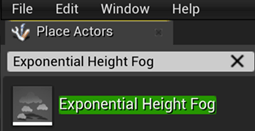

虚幻编辑器使用左手`Z`向上坐标系，其中`Y`轴指向右侧。Automated Driving Toolbox 使用右手`Z`向上坐标系，其中 `Y`轴指向左侧。在场景中定位对象时，请记住此坐标系差异。`在两个坐标系中， Y`轴和俯仰角值的正负号是相反的。

有关修改场景和添加资产的更多信息，请参阅[虚幻引擎 4 文档](https://docs.unrealengine.com/en-US/index.html)。

要将项目中的资产迁移 `AutoVrtlEnv `到您自己的项目文件中，请参阅虚幻引擎文档。

要从场景中获取语义分割数据，您必须将模板 ID 应用于添加到场景中的对象。有关详细信息，请参阅[将标签应用于虚幻场景元素以进行语义分割和对象检测](https://ww2.mathworks.cn/help/driving/ug/apply-labels-to-unreal-scene-elements-for-semantic-segmentation-and-object-detection.html)。

#### `AutoVrtlEnv `**在自定义场景中****使用投影照明**

`AutoVrtlEnv` 要使用 Automated Driving Toolbox 中的项目随附安装的照明，请按照以下步骤操作。

- 在 **World Settings **选项卡上，清除 **Force No Precomputed Lighting**。

- 在 **Build **下，选择**Lighting Quality** > **Production**以使用生产质量重建贴图。重建大型地图可能需要时间。

**运行模拟**

通过运行测试模拟来验证 Simulink 模型和 Unreal Editor 是否配置为协同模拟。

- 在 Simulink 模型中，点击**运行**。因为场景的来源是在虚幻编辑器中打开的项目，所以模拟没有启动。相反，您必须从编辑器开始模拟。

- 验证 Simulink 中的 Diagnostic Viewer 窗口是否显示以下消息：`In the Simulation 3D Scene Configuration block, you set the scene source to 'Unreal Editor'. In Unreal Editor, select 'Play' to view the scene.`此消息确认 Simulink 已在 Unreal Engine 环境中实例化车辆和其他对象。

- 在 Unreal Editor 中，点击**Play**。模拟在当前在虚幻编辑器中打开的场景中运行。

- 如果您的 Simulink 模型包含车辆，这些车辆将穿过在编辑器中打开的场景。

- 如果您的 Simulink 模型包含传感器，这些传感器会从编辑器中打开的场景捕获数据。

要在模拟期间控制场景的视图，请在 Simulation 3D Scene Configuration 模块中，从**场景视图**参数中选择车辆名称。要在模拟运行时更改场景视图，请使用编辑器中的数字键盘。该表显示了显示场景的摄像机相对于在 **场景视图** 参数中选择的车辆的位置。

要重新启动仿真，请在 Simulink 模型中单击**运行**，等待诊断查看器显示确认消息，然后在编辑器中单击**播放。**如果在模型中开始仿真之前单击 **“播放**”，Simulink 和虚幻编辑器之间的连接不会建立，并且编辑器会显示一个空场景。

如果您正在联合仿真自定义项目，要启用数字小键盘，请将 `DefaultInput.ini`文件从支持包安装文件夹复制到您的自定义项目文件夹。例如，复制 `DefaultInput.ini`自：

% C:\ProgramData\MATLAB\SupportPackages\<MATLABRelease>\toolbox\shared\sim3dprojects\driving\AutoVrtlEnv\Config

到：

% C:\<yourproject>.project\Config

根据模拟结果调整自定义场景后，您可以将场景打包成可执行文件。有关详细信息，请参阅将[自定义场景打包到可执行文件](https://ww2.mathworks.cn/help/driving/ug/package-custom-scenes-into-executable.html)中。

## 将自定义场景打包成可执行文件

当您完成自定义场景的修改后，您可以将包含该场景的项目文件打包成可执行文件。然后，您可以使用 Simulation 3D Scene Configuration 模块配置您的模型以从此可执行文件进行模拟。可执行文件可以**提高模拟性能**并且**不需要打开 虚幻编辑器来仿真**场景。相反，该场景使用随 Automated Driving Toolbox™ 一起安装的 Unreal Engine ®运行。**使用虚幻****编辑器****将场景打包成可执行文件**

在将自定义场景打包成可执行文件之前，请确保插件是：

- 位于虚幻引擎安装区，例如 `C:\Program Files\Epic Games\UE_4.26\Engine\Plugins\Marketplace\Mathworks`.

- 从您的项目区域中删除，例如， `C:\project\AutoVrtlEnv\Plugins`.

然后，按照以下步骤操作。

- 在虚幻编辑器中打开包含场景的项目。您必须从配置为与虚幻编辑器协同仿真的 Simulink ®模型打开项目。有关此配置的更多详细信息，请参阅[使用 Simulink 和虚幻编辑器自定义场景](https://ww2.mathworks.cn/help/driving/ug/customize-scenes-using-simulink-and-unreal-editor.html)。

- 确保插件内容在内容浏览器中可见。在 **View Options **下，选中**Show Engine Content**和**Show Plugin Content **复选框。

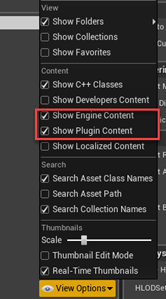

- 在虚幻编辑器工具栏中，选择**设置**>**项目设置**以打开项目设置窗口。

- 在左窗格的“**项目”**部分中，单击“**打包**” 。

- 在**打包**部分中，设置或验证表中的选项。如果您没有看到所有这些选项，请在“ **打包**”部分的底部单击“**显示高级”**扩展器.